% Package orientation: Runnable validation or benchmark wrapper. It loads saved models or constructs small checks, then reports metrics/diagnostics without changing training code.

% TEST_GPU_implementation_classification_MNIST.mlx
% Load a saved trained network and evaluate held-out MNIST classification performance.
% This script does not train. Run a CPU or GPU training script first, then choose which saved backend to load below.

clear; clc;
repo_root = project_root();
addpath(fullfile(repo_root, 'shared', 'matlab'), '-begin');
add_project_paths(repo_root);

%% ---------------- Saved Network ----------------
% This file is created by the matching train script. It stores the training options
% and the best trained bias vector. The test action reconstructs deterministic
% weights from saved options, restores best.B, and evaluates the held-out split.
test_seeds = [1 2 3]; % Independently trained initialization seeds used for release test statistics.
diagnostic_seed_index = 1; % Spike diagnostics use one representative seed to keep live plots readable.
test_backend = 'gpu'; % This script evaluates with the GPU implementation.
trained_model_backend = 'auto'; % 'auto' prefers same-backend trained models, then falls back to the other backend.
[model_files, model_file, trained_model_backend] = snn_resolve_seed_model_files(repo_root, 'classification_MNIST', test_backend, test_seeds, diagnostic_seed_index, trained_model_backend);
save_diagnostic_files = false;  % set true to write diagnostic artifacts as well as displaying inline
diag_dir = fullfile(repo_root, 'outputs', 'diagnostics', sprintf('classification_MNIST_trained_%s_test_gpu_primary', trained_model_backend));
if save_diagnostic_files && exist(diag_dir, 'dir') ~= 7, mkdir(diag_dir); end
missing_model_files = model_files(cellfun(@(f) exist(f, 'file') ~= 2, model_files));
if ~isempty(missing_model_files)
    error('Saved model(s) not found. Run the matching training script for all requested seeds first. First missing file: %s', missing_model_files{1});
end

%% ---------------- Evaluation Overrides ----------------
% model_file is required. batch_size can be lowered if GPU memory is limited.
% Other fields placed in opts override the saved training options for evaluation only.
opts = struct();
opts.model_files = model_files;
opts.seed_list = test_seeds;
opts.model_file = model_file; % Representative seed retained for diagnostics and legacy plot helpers.
opts.batch_size = 32;

%% ---------------- Run Held-Out Test ----------------
% result.test.loss is average held-out loss.

[SEED AUDIT] Verified 3 distinct fixed-network hash(es) across 3 seed(s).


% result.test.metric is accuracy (%) for the held-out split.

Testing with gpu backend; loaded gpu-trained networks for seeds [1  2  3]. Diagnostic seed file:
C:\Users\kaima\OneDrive - University of Calgary\Neural_networks_bias_learning\Spiking_neural_networks\SE adLIF\For Publication 3\GitHub_V2_multiple_architectures_working\outputs\models\classification_MNIST_gpu_primary_seed001.mat


    Seed     Loss     AccuracyPercent
    ____    ______    _______________

     1      1.2566          79.7     
     2      1.0872         81.26     
     3      1.2511         79.27     



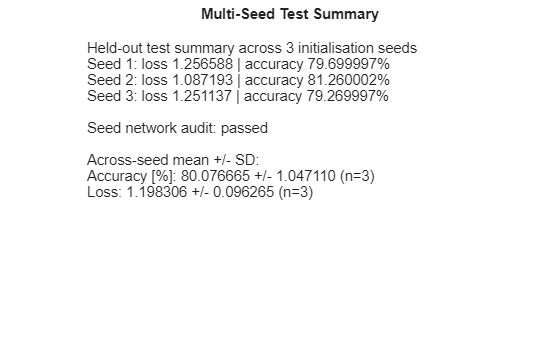

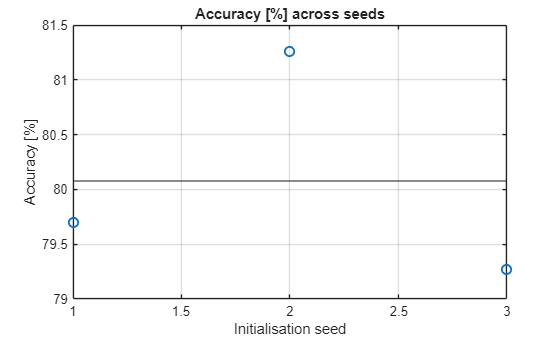

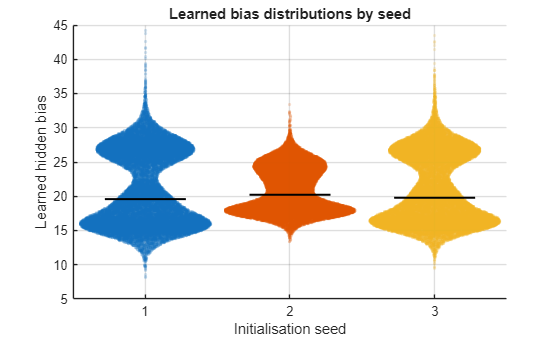

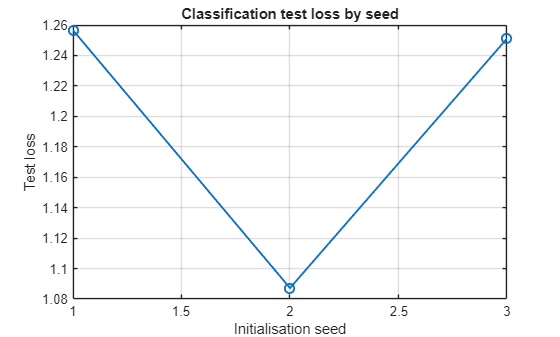

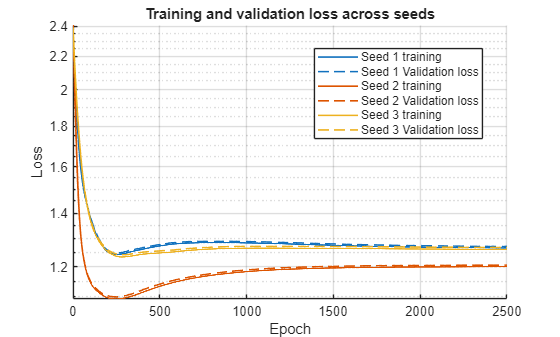

result = snn_primary_api('test_static', 'classification', test_backend, opts);


=== Spiking Diagnostics: mnist_test_classification ===
Samples: 8 | Neurons: 32000 | Steps/sample: 300 | Seconds/sample: 0.3
Mean neuron firing rate: 6.85668 Hz | median 2.91667 Hz | 95th percentile 17.9167 Hz
Active neurons: 23523 / 32000 (73.51%)
Silent neurons: 8477 / 32000 (26.49%)
Mean population rate by sample: 6.85668 Hz/neuron
Mean active neurons by sample: 53.23% | silent 46.77%
Total within-sample ISIs counted: 390327
Median per-neuron mean inverse-ISI rate: 15.7808 Hz


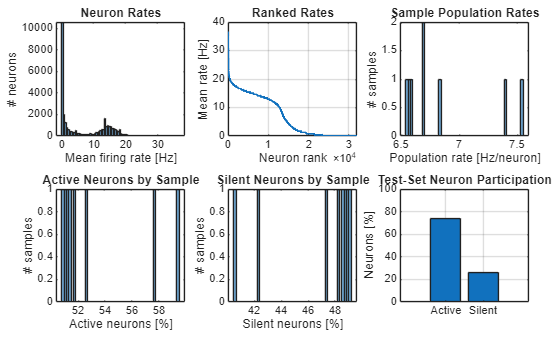

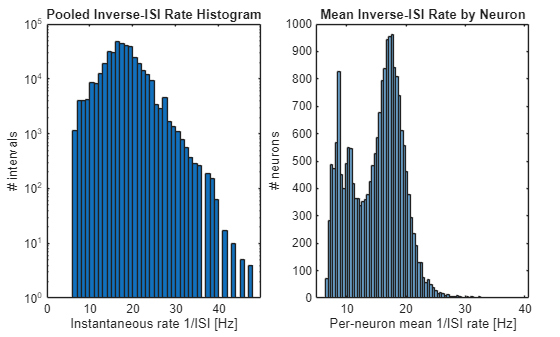

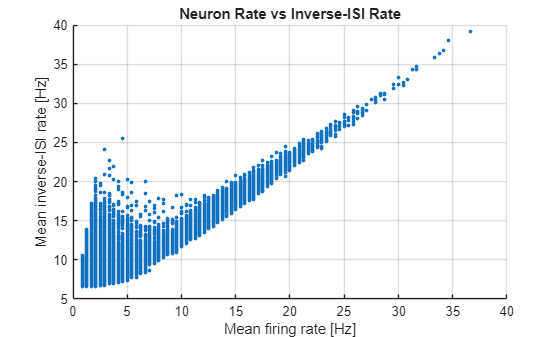

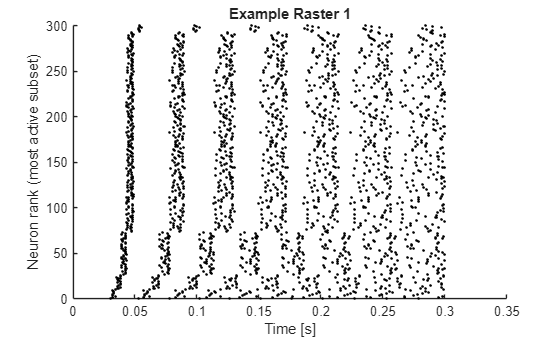

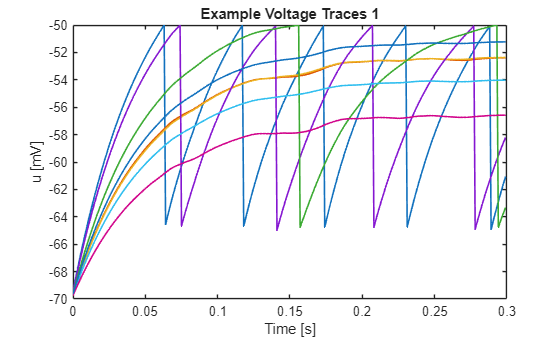

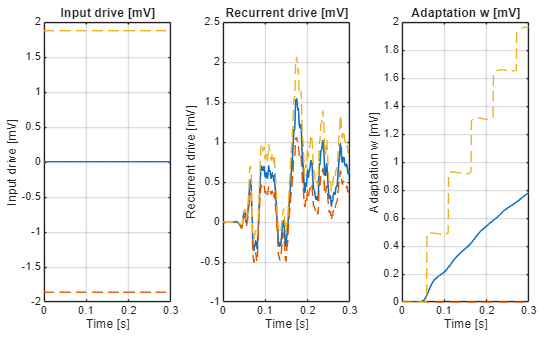

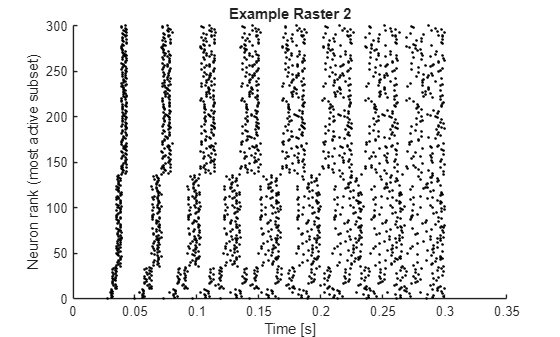

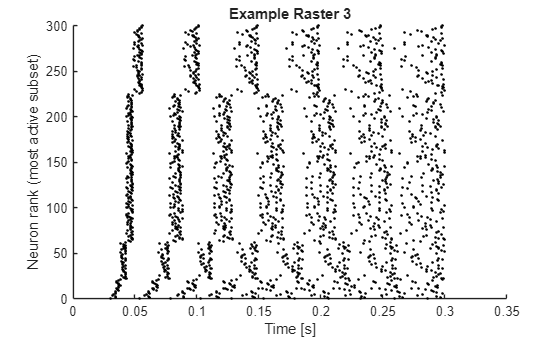

[SPIKING] Displayed spiking diagnostics without saving files. To save files, pass 'save_files', true.


fprintf('Testing with %s backend; loaded %s-trained networks for seeds [%s]. Diagnostic seed file:\n%s\n', test_backend, trained_model_backend, num2str(test_seeds), model_file);
snn_plot_test_result(result);

%% ---------------- Spiking Dynamics Diagnostics ----------------
% These diagnostics replay the saved trained network through the CPU reference
% to produce spike rasters, firing-rate summaries, ISI histograms, voltage traces,
% input/recurrent/adaptation current summaries. By default they display inline only.
diag_opts = struct();
diag_opts.model_file = model_file;
diag_opts.output_dir = diag_dir;
diag_opts.save_files = save_diagnostic_files;

diag_opts.max_samples = 8;
diag = snn_primary_api('spike_diagnostics_static', 'classification', 'cpu', diag_opts);
fprintf('Test spiking active neurons: %.2f%%%% (%d/%d); silent neurons: %.2f%%%% (%d/%d).\n', ...

Test spiking active neurons: 73.51%% (23523/32000); silent neurons: 26.49%% (8477/32000).


    diag.active_neuron_percent, diag.active_neuron_count, diag.n_neurons, ...
    diag.silent_neuron_percent, diag.silent_neuron_count, diag.n_neurons);

Mean per-sample active neurons: 53.23%%; silent neurons: 46.77%%.


fprintf('Mean per-sample active neurons: %.2f%%%%; silent neurons: %.2f%%%%.\n', ...

Loaded trained network from:
C:\Users\kaima\OneDrive - University of Calgary\Neural_networks_bias_learning\Spiking_neural_networks\SE adLIF\For Publication 3\GitHub_V2_multiple_architectures_working\outputs\models\classification_MNIST_gpu_primary_seed001.mat


    mean(diag.active_percent_by_sample), mean(diag.silent_percent_by_sample));

Displayed test plots and spiking diagnostics inline. Set save_diagnostic_files=true to write diagnostics to disk.


fprintf('Loaded trained network from:\n%s\n', model_file);

      loss: 1.2566
    metric: 79.7000
     count: 10000
         Z: [10×10000 single]
         Y: [10×10000 single]



fprintf('Displayed test plots and spiking diagnostics inline. Set save_diagnostic_files=true to write diagnostics to disk.\n');
disp(result.test);
